clc
clear
close all

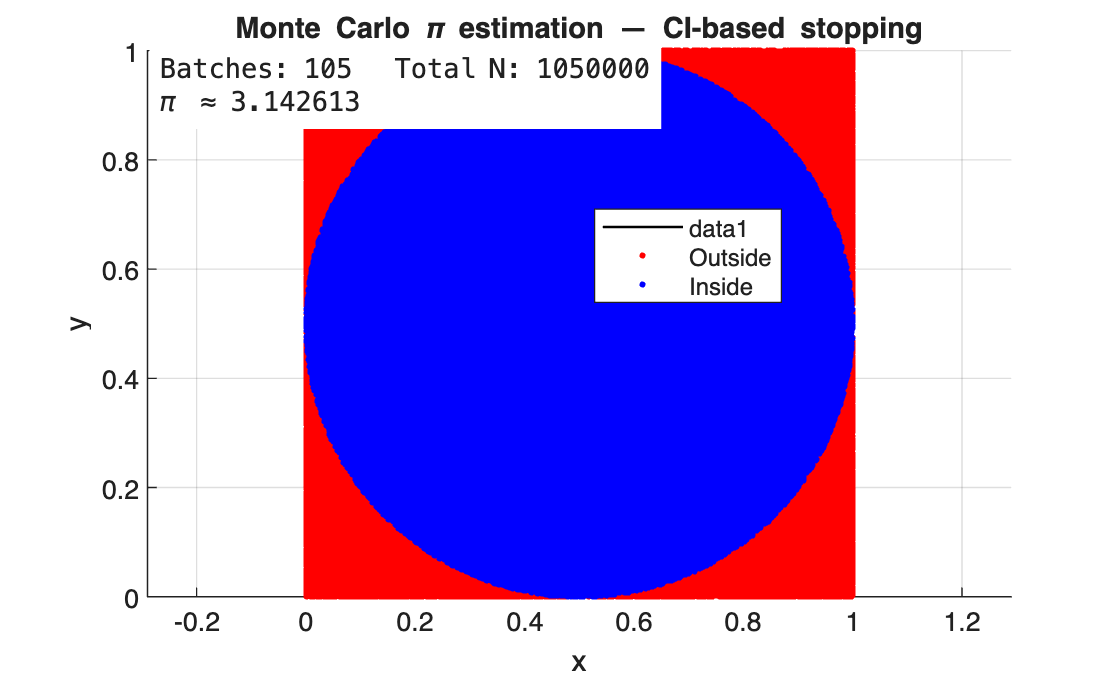

Total points = 1050000 (batch size 10000, batches 105)
95% CI half-width: 3.140e-03   (relative: 9.991e-04)
Final pi (rounded to precision=0.001): 3.143


pi_value =    3.143000000000000


pi_value = MC_pi(1e-3)

function pi_value = MC_pi(precision)

    cx = 0.5; cy = 0.5;      % circle center
    r  = 0.5; r2 = r^2;      % radius and radius^2

    z = 1.96;                % ~95% confidence interval

    batchN     = 10000;       % points per visual update (tune for speed/smoothness)
    maxBatches = 1e6;        % safety cap (total points ≈ batchN*maxBatches)

    hits_total = 0;
    N_total    = 0;

    figure('Name','Monte Carlo \pi (CI-based)','Color','w');
    ax = axes('XLim',[0 1],'YLim',[0 1]); axis(ax,'equal'); grid(ax,'on'); hold(ax,'on');
    xlabel(ax,'x'); ylabel(ax,'y');
    title(ax,'Monte Carlo \pi estimation — CI-based stopping');

    th = linspace(0,2*pi,400);
    plot(ax, cx + r*cos(th), cy + r*sin(th), 'k-', 'LineWidth', 1.0);

    hOut = plot(ax, nan, nan, '.r', 'MarkerSize', 7, 'DisplayName','Outside');
    hIn  = plot(ax, nan, nan, '.b', 'MarkerSize', 7, 'DisplayName','Inside');
    legend(ax,'Location','best');

    hTxt = text(ax, 0.01, 0.99, '', 'Units','normalized', ...
                'HorizontalAlignment','left','VerticalAlignment','top', ...
                'FontName','monospace','BackgroundColor','w');

    Xin = []; Yin = [];  % inside points shown
    Xout = []; Yout = []; % outside points shown
    visCap = 2e5;        % cap the number of displayed points

    batch = 0;
    moe = inf; rel_moe = inf; pi_hat = NaN;

    while (rel_moe > precision) && (batch < maxBatches)
        batch = batch + 1;

        X = rand(2, batchN);

        D2 = (X(1,:)-cx).^2 + (X(2,:)-cy).^2;
        k  = (D2 <= r2);
        hits = nnz(k);

        hits_total = hits_total + hits;
        N_total    = N_total + batchN;

        p_hat  = hits_total / N_total;
        pi_hat = p_hat / r2;
        se     = sqrt(p_hat*(1-p_hat)/N_total) / r2;
        moe    = z * se;                     % absolute half-width
        rel_moe = moe / max(pi_hat, eps);    % relative half-width

        Xin  = [Xin,  X(1,k)];  Yin  = [Yin,  X(2,k)];
        Xout = [Xout, X(1,~k)];  Yout = [Yout, X(2,~k)];
        if numel(Xin) > visCap
            keep = floor(visCap/2);
            Xin = Xin(end-keep+1:end); Yin = Yin(end-keep+1:end);
        end
        if numel(Xout) > visCap
            keep = floor(visCap/2);
            Xout = Xout(end-keep+1:end); Yout = Yout(end-keep+1:end);
        end

        set(hIn,  'XData', Xin,  'YData', Yin);
        set(hOut, 'XData', Xout, 'YData', Yout);
        set(hTxt, 'String', sprintf([ ...
            'Batches: %d   Total N: %d\n' ...
            '\\pi \\approx %.6f'], ...
            batch, N_total, pi_hat));
        drawnow
        pause(0.01)
    end


    dec = max(0, ceil(-log10(precision)));     % e.g., 0.005 -> 3 decimals
    pi_value = round(pi_hat, dec);             % round to that many decimals

    fprintf('Total points = %d (batch size %d, batches %d)\n', N_total, batchN, batch);
    fprintf('95%% CI half-width: %.3e   (relative: %.3e)\n', moe, rel_moe);
    fprintf('Final pi (rounded to precision=%g): %.*f\n', precision, dec, pi_value);


end